## Read three orthonormal-view images and convert to grayscale

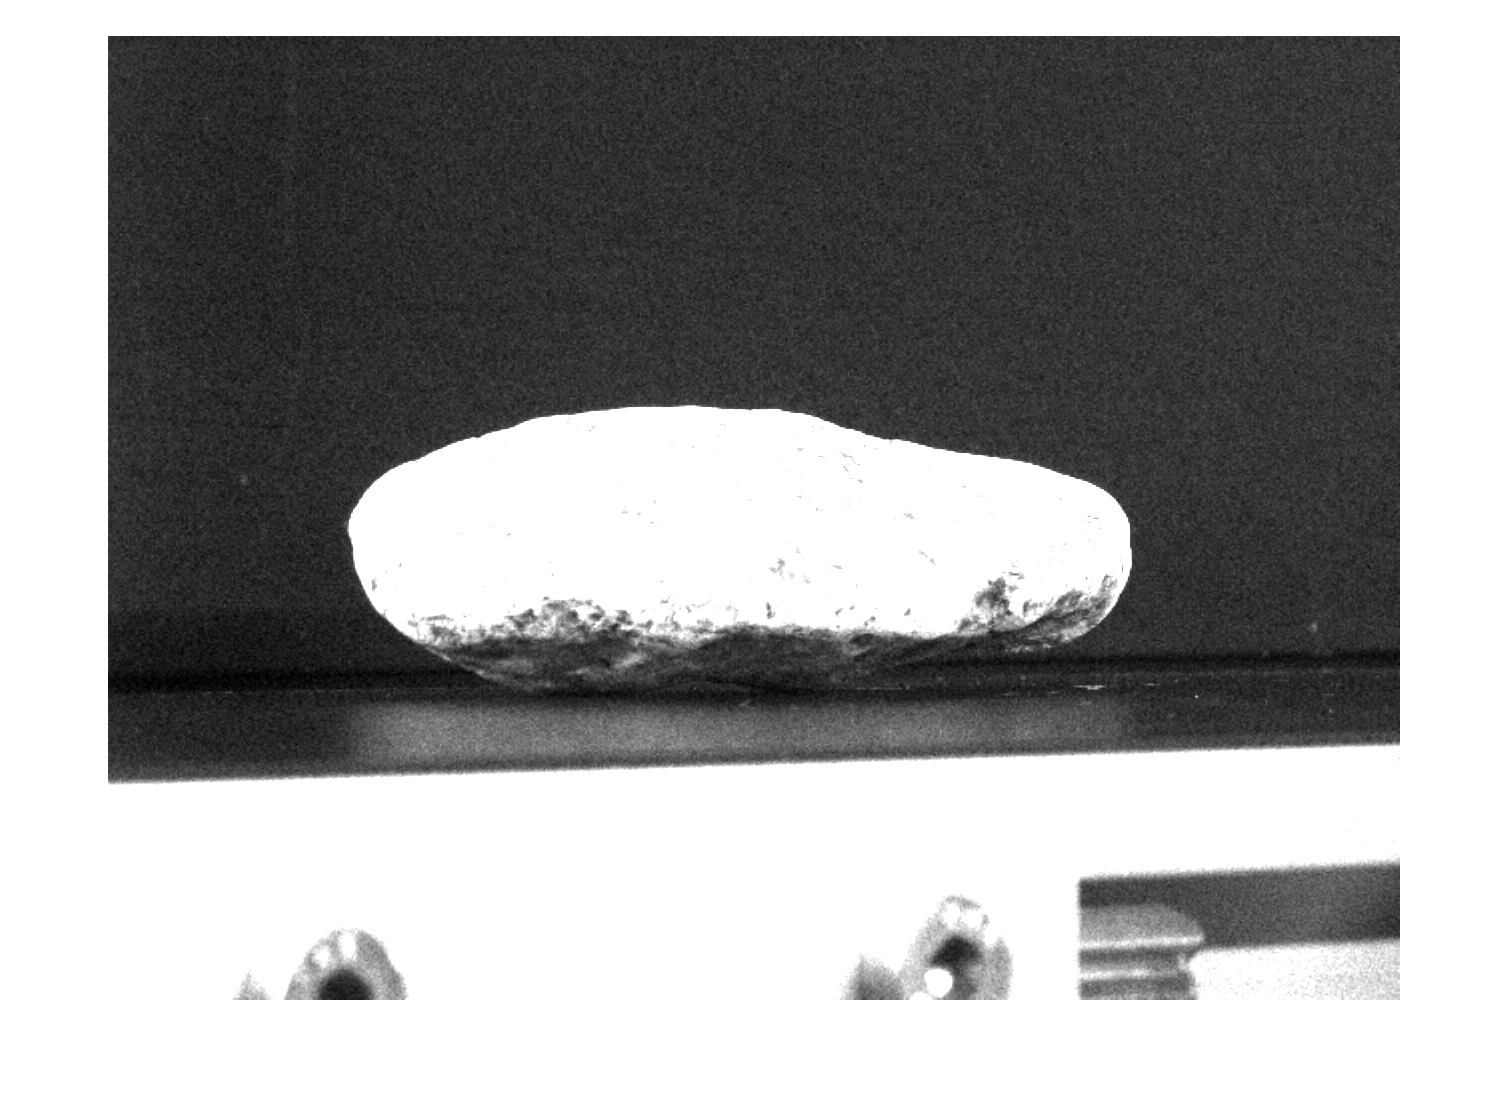

% front = imread('front.bmp');
% side = imread('side.bmp');
% top = imread('top.bmp');
front = imread('front_1.png');
% side = imread('side_1.png');
% top = imread('top_1.png');
close all
figure;
imshow(front(:,:,1));


% figure
% [ha, pos] = tight_subplot(2,3,[.01 .01],[.01 .01],[.01 .01]);
% axes(ha(1)), imshow(front), title('front'); 
% axes(ha(2)), imshow(side), title('side');
% axes(ha(3)); imshow(top), title('top');

## Convert to binary image with thresholding and edge detection

front_bi = toBinary(rgb2gray(front));

Error using  - 
Integers can only be combined with integers of the same class, or scalar doubles.

Error in reconstruct>toBinary (line 49)
        if sum((squeeze(im(i,j,:)) - blue).^2) > 0.3

% side_bi = toBinary(rgb2gray(side));
%top_bi = toBinary(rgb2gray(top));
figure
imshow(front_bi)
% axes(ha(4)); imshow(front_bi), title('front');
% axes(ha(5)); imshow(side_bi), title('side');
% axes(ha(6)); imshow(top_bi), title('top')

% textContent = {'Original images', 'Binary images'};
% textPos = {[0 0.9 1 0.1], [0 0.4 1 0.1]}; % relative location w.r.t to the figure
% for i = 1:2
%     annotation('textbox', textPos{i}, ... 
%                'String', textContent{i}, ...
%                'EdgeColor', 'none', ...
%                'HorizontalAlignment', 'center',...
%                'FitBoxToText','on',...
%                'FontWeight','bold') 
% end

## toBinary()

@param im The input image

@return The desired binary image

function im = toBinary(im)
% This if for ZJU-type image that has dark particle-white background
%     im = imgaussfilt(im, 2); % Gaussian filtering with sigma = 2
%     im = imbinarize(im,0.7); % Binarize with threshold = 0.7. Illuminance > threshod, true; otherwise, false
%     im = imclearborder(~im, 8); % Only take the object that is in center of the image
%     im = imfill(im, 8, 'holes'); % Fill holes in the mask. Note the object (particle) is always darker than background, use ~ (NOT) operator

% Color segmentation is used for UIUC-type image that has bright particle-blue background
% Refer to Blobsdemo.m provided by Image Analyst on Matlab Forum
    im = imgaussfilt(im, 2); % Gaussian filtering with sigma = 2
mask = false(size(im));
blue = [0.0;0.0;1.0];
for i = 1:size(im,1)
    for j = i:size(im,2)
        if sum((squeeze(im(i,j,:)) - blue).^2) > 0.3
            mask(i,j) = true;
        end
    end
end
im = mask
    %im = imbinarize(im,0.7); % Binarize with threshold = 0.7. Illuminance > threshod, true; otherwise, false
    im = imclearborder(~im, 8); % Only take the object that is in center of the image
    im = imfill(im, 8, 'holes');
end


%cc = bwconncomp(im, 8);

% [h, w] = size(im);
% seed = false(h,w);
% seed(floor(h/2), floor(w/2)) = true;
% W = gradientweight(im, 1.0);
% thresh = 0.1;
% [BW, D] = imsegfmm(W, seed, thresh);
% imshow(BW)

% bm = boundarymask(front);
% imshow(bm);